Before starting the tutorial please update your path so that you can access the need functions and and datasets

each cell can be run by pressing Ctrl+Enter, by pressing the button "Run Section", or changing a parameter value on one of the sliders


CurrDirectory=pwd;
addpath(genpath(CurrDirectory));

## Exercise 1 load the single slice k-space data and compute the image

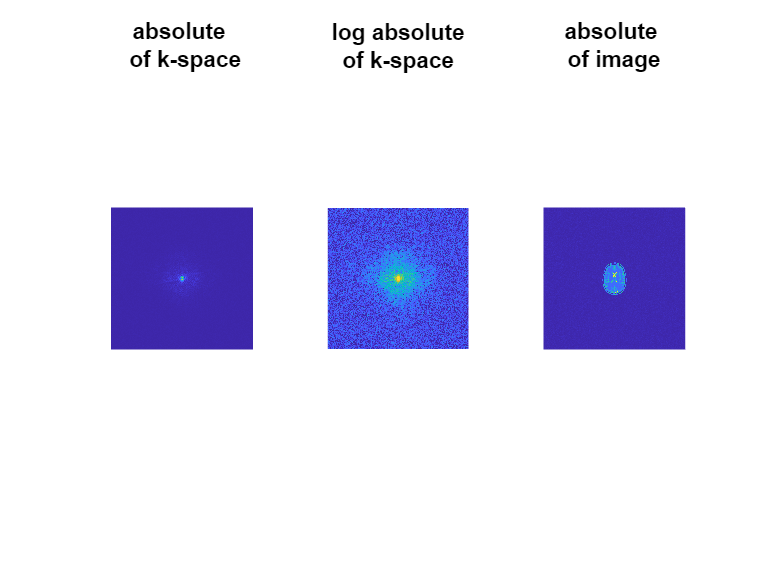

clear

% 1a load the data
load kspacedata
close all


% 1b look at the kspace data using imagesc
figureJ(1)
subplot(131)
imagesc(abs(kspace)), axis off, axis equal
title({'absolute ' ' of k-space'})

subplot(132)
imagesc(log(abs(kspace)),[2 8]), axis off, axis equal
title({'log absolute' 'of k-space'})

% 1c compute the image using the matlab function fft and fftshift instead of my function ifft2s

Im=ifft2s(kspace);

figure(1)
subplot(133)
imagesc(abs(Im)), axis off, axis equal
title({'absolute ' 'of image'} )
fontScale(1.4)

## Exercise 2 whoever prescribed the protocol asked for a very large FOV;

create a reduced field of view by downsampling the k space data specify the indexes of kspace you want to use. by how much could you have reduced the the acquisition time if this was a 2D or a 3D acquisition?

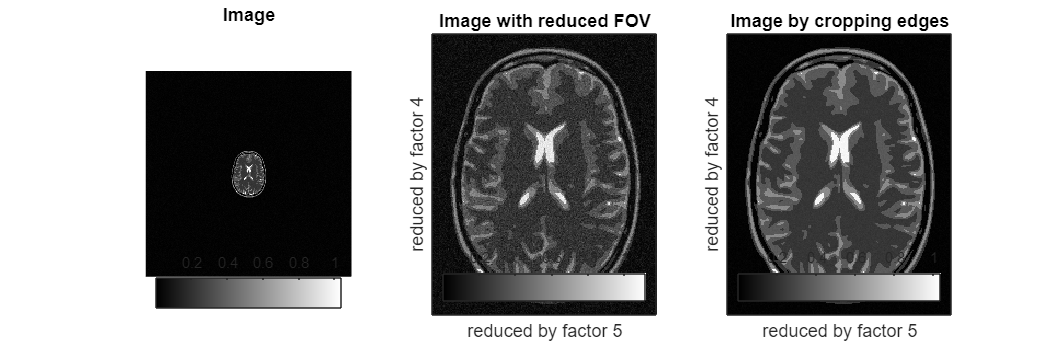

redFactorx = 4;
redFactory = 5;

kspace_redFOV = kspace(1:redFactorx:end,1:redFactory:end);
% by increasing the spacing between succesive points in k-space by redFactor,
% the FOV is reduced by this same factor

Im_redFOV = ifft2s(kspace_redFOV);
%
dims    = size(kspace_redFOV);

% alternatively you could simply take the larger FOV image and crop it
% directly in the image space
Im_redFOV_bycropping=crop(Im,dims);

VisualizeReducedFOV(Im,Im_redFOV,Im_redFOV_bycropping,redFactorx,redFactory)

what differences do you see? Why does the data sudenly look so much noisier? 

if you would have changed the FOV simply by croppping the image in the real space

## Exercise 3 given the amount of SNR available in the new FOV dataset, it is maybe better to have a lower resolution currently the prescribed resolution was 0.85... lets make it 1.7

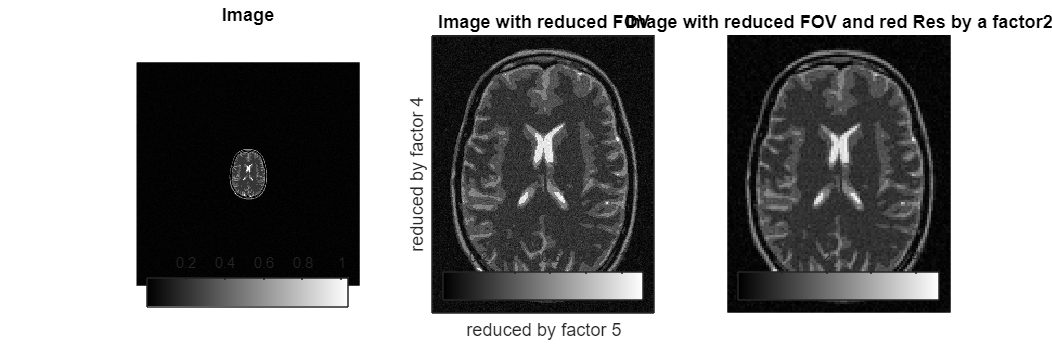

RedRes  = 2;

dimsnew = round(dims/RedRes);

kspace_redFOV_redRES =...
    crop(kspace_redFOV,dimsnew);

% note that by reducing the extent of k-space (done by only taking the
% central part of the k-space), the resolution is automatically reduced.

Im_redFOV_redRES = ifft2s(kspace_redFOV_redRES);


VisualizeReducedResolution (Im,Im_redFOV,Im_redFOV_redRES,redFactorx,redFactory,RedRes)

## Exercise 4 Try to formulate the dependence of SNR in the number of phase encoding steps used and the resolution;

Given that the top left square in the image is always background signal, this region will be used to estimate the level of noise of this image.

temp  = (Im( 1:15 , 1:15 ));
Noise = std(temp(:));
temp  = (Im_redFOV( 1:15 , 1:15 ));
Noise_redFOV = std(temp(:));
temp  = (Im_redFOV_redRES( 1:15 , 1:15 ));
Noise_redFOV_redRES = std(temp(:));


display([' In exercise 2, the pixel volume was not changed'])

 In exercise 2, the pixel volume was not changed


display([' when reducing the number of PE steps by ', num2str(redFactorx*redFactory)]);

 when reducing the number of PE steps by 20


display([' the increase of noise level was of ',num2str(Noise_redFOV/Noise)]);

 the increase of noise level was of 4.3428


display([' ']);

display([' the dependence of the SNR on the number of phase encoding steps is proportional to the square root of the phase encoding steps']);

 the dependence of the SNR on the number of phase encoding steps is proportional to the square root of the phase encoding steps


display([' you can use other FOV reduction factors in exercise 2 to see if this relationship holds']);

 you can use other FOV reduction factors in exercise 2 to see if this relationship holds


display([' ']);

display(['In Exercise 3, when changing the voxel resolution'])

In Exercise 3, when changing the voxel resolution


display(['when increasing the volume by ', num2str(RedRes*RedRes)]);

when increasing the volume by 4


display(['the decrease of noise level was of ',num2str(Noise_redFOV_redRES/Noise_redFOV)]);

the decrease of noise level was of 2.0472


display(['but you should also factor in that you decreased the number of phase encoding steps']);

but you should also factor in that you decreased the number of phase encoding steps




% as a measure of the signal amplitude you can use the cursor to select a
% region of interest in the tissue of your choice and see how did the
% signal change. (altenatively you can simply look at the range shown by the colorbar)

## Exercise 5

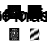


%Coordinate which information we want to check... you can change the
%coordinate position by changing ks_coord and ky_coord
kx_coord=-10;
ky_coord=10;
% if  n_neighbours = zero, only the info in that coordinate is kept,
% if a bigger number is the n_neighbours pixels on eaach side are also kept
n_neighbours=0;

% calculating the k-space mask
dimsnew=size(kspace_redFOV_redRES);
mask=zeros(dimsnew);
mask(kx_coord+floor(dimsnew(1)/2+1)+[-n_neighbours:n_neighbours],ky_coord+floor(dimsnew(2)/2+1)+[-n_neighbours:n_neighbours])=1;

% calculates image associated with the masked k-space
Im_masked=ifft2s(kspace_redFOV_redRES.*mask);

% note that matlab x and y conventions are a bit unexpected
VisualizeKspaceMask(kspace_redFOV_redRES , mask ,Im_redFOV_redRES  , Im_masked)

Why is the k-space matrix square, but not the image?

## ** Tutorial on paralel imaging      **

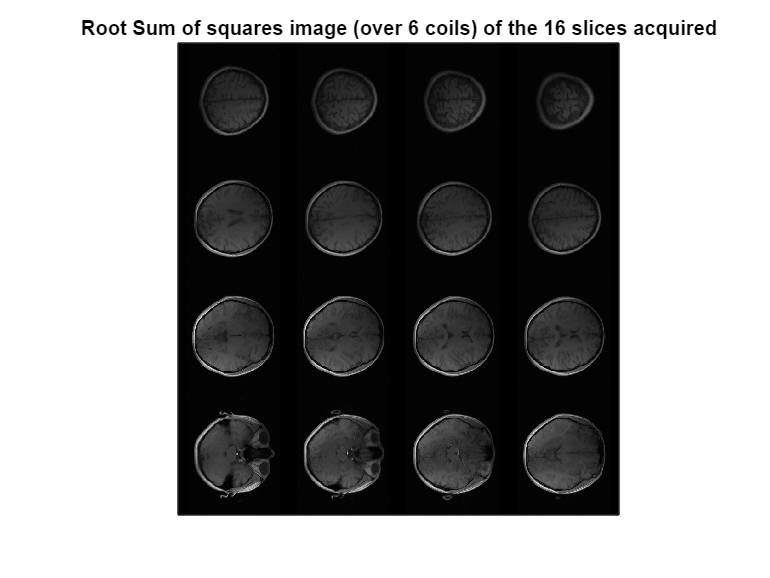


% load all data - multicoil imaging data and coild sensitivities
clear
close all
figureJ(10)

load('DATA/imgT1fl2d_tra.mat');
imgAllSlices  = imgT1fl2d_tra; clear imgT1fl2d_tra;
load('DATA/cmapT1fl2d_tra.mat');
cmapAllSlices = cmapT1fl2d_tra; clear cmapT1fl2d_tra;

imab(sos(imgAllSlices,1),[],0,4);

title('Root Sum of squares image (over 6 coils) of the 16 slices acquired')
colormap gray

## Exercises 6

doing simply inplane acceleration

Data were complex - absolute values are shown
Data were complex - absolute values are shown


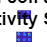

inputs are integer valued, you can proceed


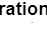

...64...128...192...256


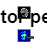

%choose the slices you are exciting - less slices make the computation
%faster
Slice = [8];
%choose the acceleration factor you will use for this slice
AccelerationFactor = 4;

ParallelImagingSimulationAndRecon(imgAllSlices,cmapAllSlices,Slice,AccelerationFactor,1);

## Exercise 7 and 8

Doing multiband acceleration

While the code does allow you to use the sliders.. it can make it slow

use this code to evaluate the impact of SMS, caipi factors and slice spacing as wella s combination with inplane acceleration 

Data were complex - absolute values are shown
Data were complex - absolute values are shown
Data were complex - absolute values are shown
Data were complex - absolute values are shown
Data were complex - absolute values are shown
Data were complex - absolute values are shown


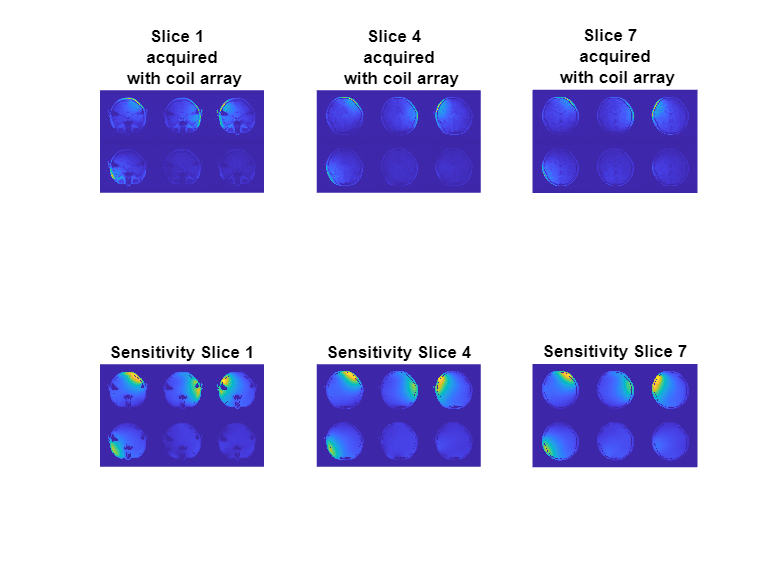

inputs are integer valued, you can proceed


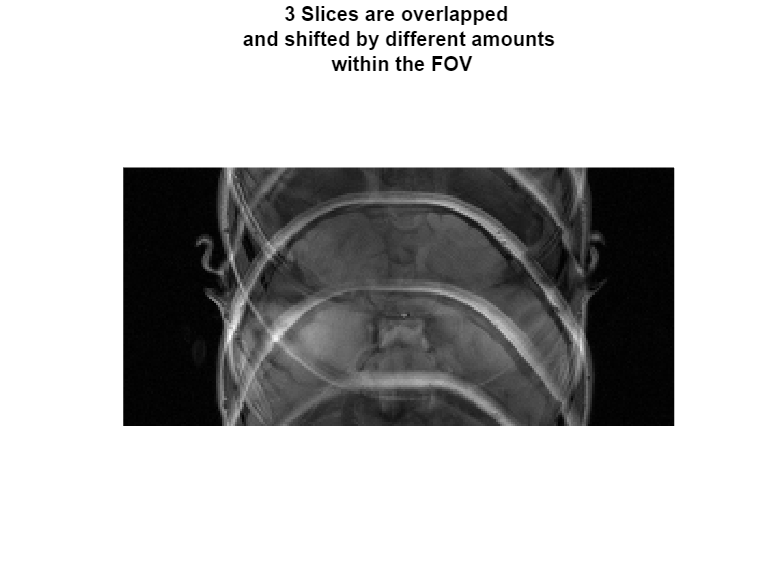

...64...128...192...256


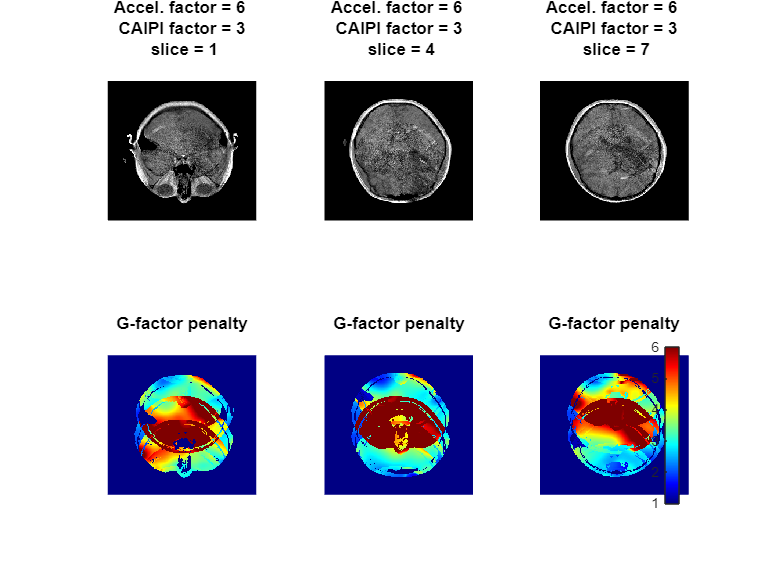

% select the spacing between slices to simultaneously excite
SMSfactor = 3;
SpacingBetweenSlices = 3 ;
% choose your CAIPI factor
CaipiFactor = 3;
% select inplane accleration,
InplaneAcceleration =2;

FirstSlice = 1 ;


Slices = FirstSlice + [0:SMSfactor-1]*SpacingBetweenSlices;
if max(Slices) > size(cmapAllSlices,4);
    error('you are exciting beyond your imaging volume , consider reducing SMS factor or spacing')
else

    % Note that the total acceleration is given by the number of simultaneously excited
    % slices time the inplane acceleration
    TotalAcceleration = length(Slices)* InplaneAcceleration;



    ParallelImagingSimulationAndRecon(imgAllSlices,cmapAllSlices,Slices,TotalAcceleration,CaipiFactor);
end;